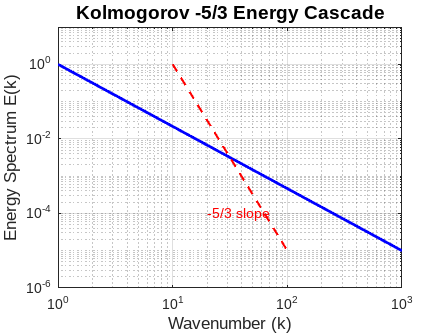

% Energy Cascade - Kolmogorov -5/3 Spectrum
clear; close all; clc

% Create wavenumber array (k) - log spaced
k = logspace(0,3,100); % from 1 to 1000, 100 points

% Energy spectrum following Kolmogorov's -5/3 Law
E = k.^(-5/3);

% Plot
loglog(k, E, 'LineWidth', 2, 'Color', 'b')
grid on
xlabel('Wavenumber (k)', 'FontSize', 12)
ylabel('Energy Spectrum E(k)', 'FontSize', 12)
title('Kolmogorov -5/3 Energy Cascade', 'FontSize', 14)
xlim([1 1000])
ylim([1e-6 10])

% Add -5/3 slope guide (optional)
hold on
k_slope = [10 100];
E_slope = [1 1e-5];
loglog(k_slope, E_slope, '--r', 'LineWidth', 1.5)
text(20, 1e-4, '-5/3 slope', 'Color', 'r')